# PLCTools, the Plotting Tool for the Power Law Creep (PLC) Toolbox

This demo demonstrates many of the capabilities of PLCTools, such as plotting Power Law Creep (PLC) Toolbox outputs as 2D images, creating 1D plots of values across a horizontal, vertical, or diagonal cut plane / cross section, masking grains by phase, and calculating the gradient of the parameter of interest (such as stress, strain, etc.).

Keep in mind that PLCTools can be leveraged from any regular MATLAB script (.m file) or through the MATLAB Command Window. The purpose of this demo is to provide examples of the syntax and workflow for performing calculations on and visualization of PLC results.

To run this demo, define all variables listed in the **Setup** section, then click *Run All* in the 'Live Editor' tab. Two distinct cases are presented in this demo:

- Visualization of a single PLC run

- Visualization of multiple PLC runs in which a characteristic (in this case, the frequency of a sawtooth wave) changes from run to run

**Dependencies**:

***MATLAB Image Processing Toolbox***

***MATLAB Curve Fitting Toolbox***

PLCTools uses a normalized coordinate system in which the maximum value of the largest dimension is 1, or as in the case of the square shown below, both the x and y dimensions span from 0 to 1:

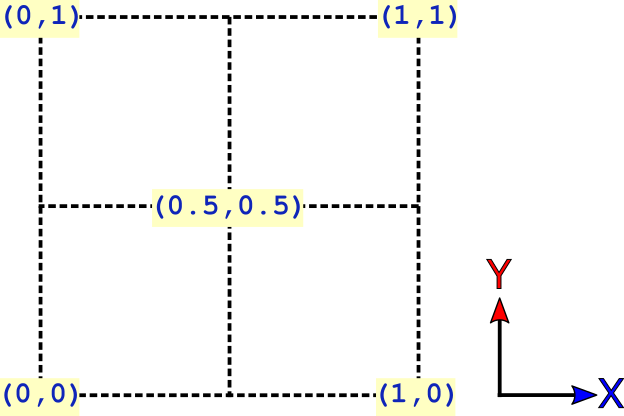

**NOTE**: The vertices labeled above are for demonstration only. When designating cut line vertices, use any vertex pair you please within the domain.

## Set The Path

Show MATLAB where the PLCTools DEMO_DATA directory is by prompting a dialogue which sets the path:

if (exist('DemoDirectory','var') == 0) || (isempty(DemoDirectory) == 1)
    DemoDirectory = uigetdir(userpath,'Select PLCTools "DEMO_DATA" directory');
end

## **K-Value explainer from PLC literature:**

For **STRESSES**, k is as follows:

-   k=1 for deviatoric sigma_11 

-   k=2 for deviatoric sigma_22 

-   k=3 for deviatoric sigma_33 

-   k=4 for tau_32 

-   k=5 for tau_31 

-   k=6 for tau_12 

-   k=7 for max. principal dev. stress sigma1p 

-   k=8 for min. principal dev. stress sigma3p 

-   k=9 for max. shear stress 

-   k=10 for 2nd invariant of stress 

-   k=11 for trace of stress tensor (which can be used to obtain normal components)

For **STRAIN RATES**, k is as follows:

-   k=1 for epsdot_11 

-   k=2 for epsdot_22 

-   k=3 for epsdot_33 

-   k=4 for gammadot_32 

-   k=5 for gammadot_31 

-   k=6 for gammadot_12 

-   k=7 for max. principal strain rate epsdot_1p 

-   k=8 for min. principal strain rate epsdot_3p 

-   k=9 for 2nd strain rate invariant 

-   k=10 for trace of strain rate tensor (which can be used to obtain normal components) 

## (1) Plot a single PLC run

In this simple example, calculations and visualization will be performed on a single PLC run without masking any phases.

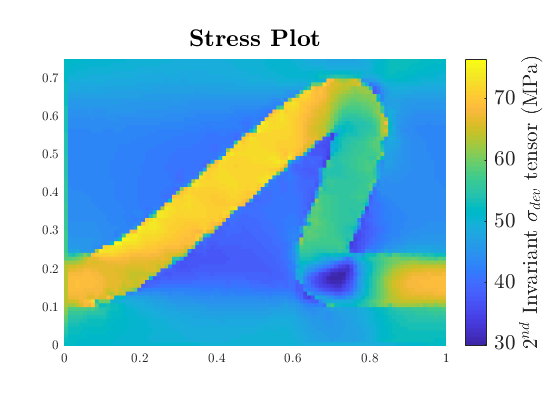

%%% PERFORM CALCULATIONS AND PLOT RESULTS FOR A SINGLE RUN %%%

% ASSIGN A PROJECT NAME
project_name = 'Fold';

% SELECT THE PLC PARAMETERS OF INTEREST
parameter = 'Stress'; % choose between 'Stress' 'Strain' 'Viscosity' or 'PowerDissipationDensity'
temperature_interval = 1; % declare which PLC temperature interval is of interest
stress_strain_interval = 2; % declare which applied macro strain rate or stress 
    % interval is of interest
k_value = 10; % see k-value explainer above

% CHANGE TO THE DIRECTORY WHERE THE PLC OUTPUT IS STORED
try
    cd(DemoDirectory)
catch
    msg = ['Wrong DemoDirectory supplied. Select the directory ', ...
          'one level above where results (PLC output) are stored.'];
    DemoDirectory = uigetdir(userpath,msg);
    cd(DemoDirectory)
end
cd('Fold3cgsm30_2m_9d_11h_59m')

% INITIALIZE THE PLC OBJECT
plc = PLCobject(parameter,temperature_interval,...
    stress_strain_interval,'kValue',k_value);

% CALCULATE THE STRESS GRADIENT
plc = plc.CalculateGradient;

% DEFINE A LINE OF CROSS SECTION
xc_vertices_begin = [0.15,0.15;... % [x1,y1;... vertex 1 of the first cut line
                    0.65,0.65];    % x2,y2];    vertex 2 of the first cut line
plc = plc.SetCutLine(xc_vertices_begin);
cut_line_length = plc.vertex_distance;

% RETURN THE GRADIENT ALONG THE LINE OF
% CROSS SECTION (accessible as 'plc.gradient_cutline')
plc = plc.CutLineGradient();

% PLOT PREFERENCES
x_axis_label = 'Length of Cut Line';
x_axis_unit = '(pixels)';
y_axis_label = '$2^{nd}$ Invariant $\sigma_{dev}$ tensor';
y_axis_unit = '(MPa)';
y_axis_gradient_unit = '(MPa/pixel)';

% PLOT THE STRESS FIELD
parameterplot = figure('units','normalized'); % initialize plot of the entire domain
set(parameterplot,'Renderer','opengl','GraphicsSmoothing','on');
plc.plot(parameterplot,plc.results);
set(gca,'TickLabelInterpreter','latex',...
    'fontname','Century Schoolbook',...
    'DataAspectRatio',[1 1 1])
title(['\textbf{','Stress Plot','}'],...
        'Interpreter','latex','fontname','Century Schoolbook',...
        'FontSize',18);
% set(gca, 'visible', 'off') % remove the axes markers
set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
c = colorbar;
c.Label.String = [y_axis_label,' ',y_axis_unit];
set(c,'TickLabelInterpreter','latex',...
    'fontname','Century Schoolbook','fontsize',16)
set(c.Label,'Interpreter','latex',...
    'fontname','Century Schoolbook','fontsize',16)
caxis auto

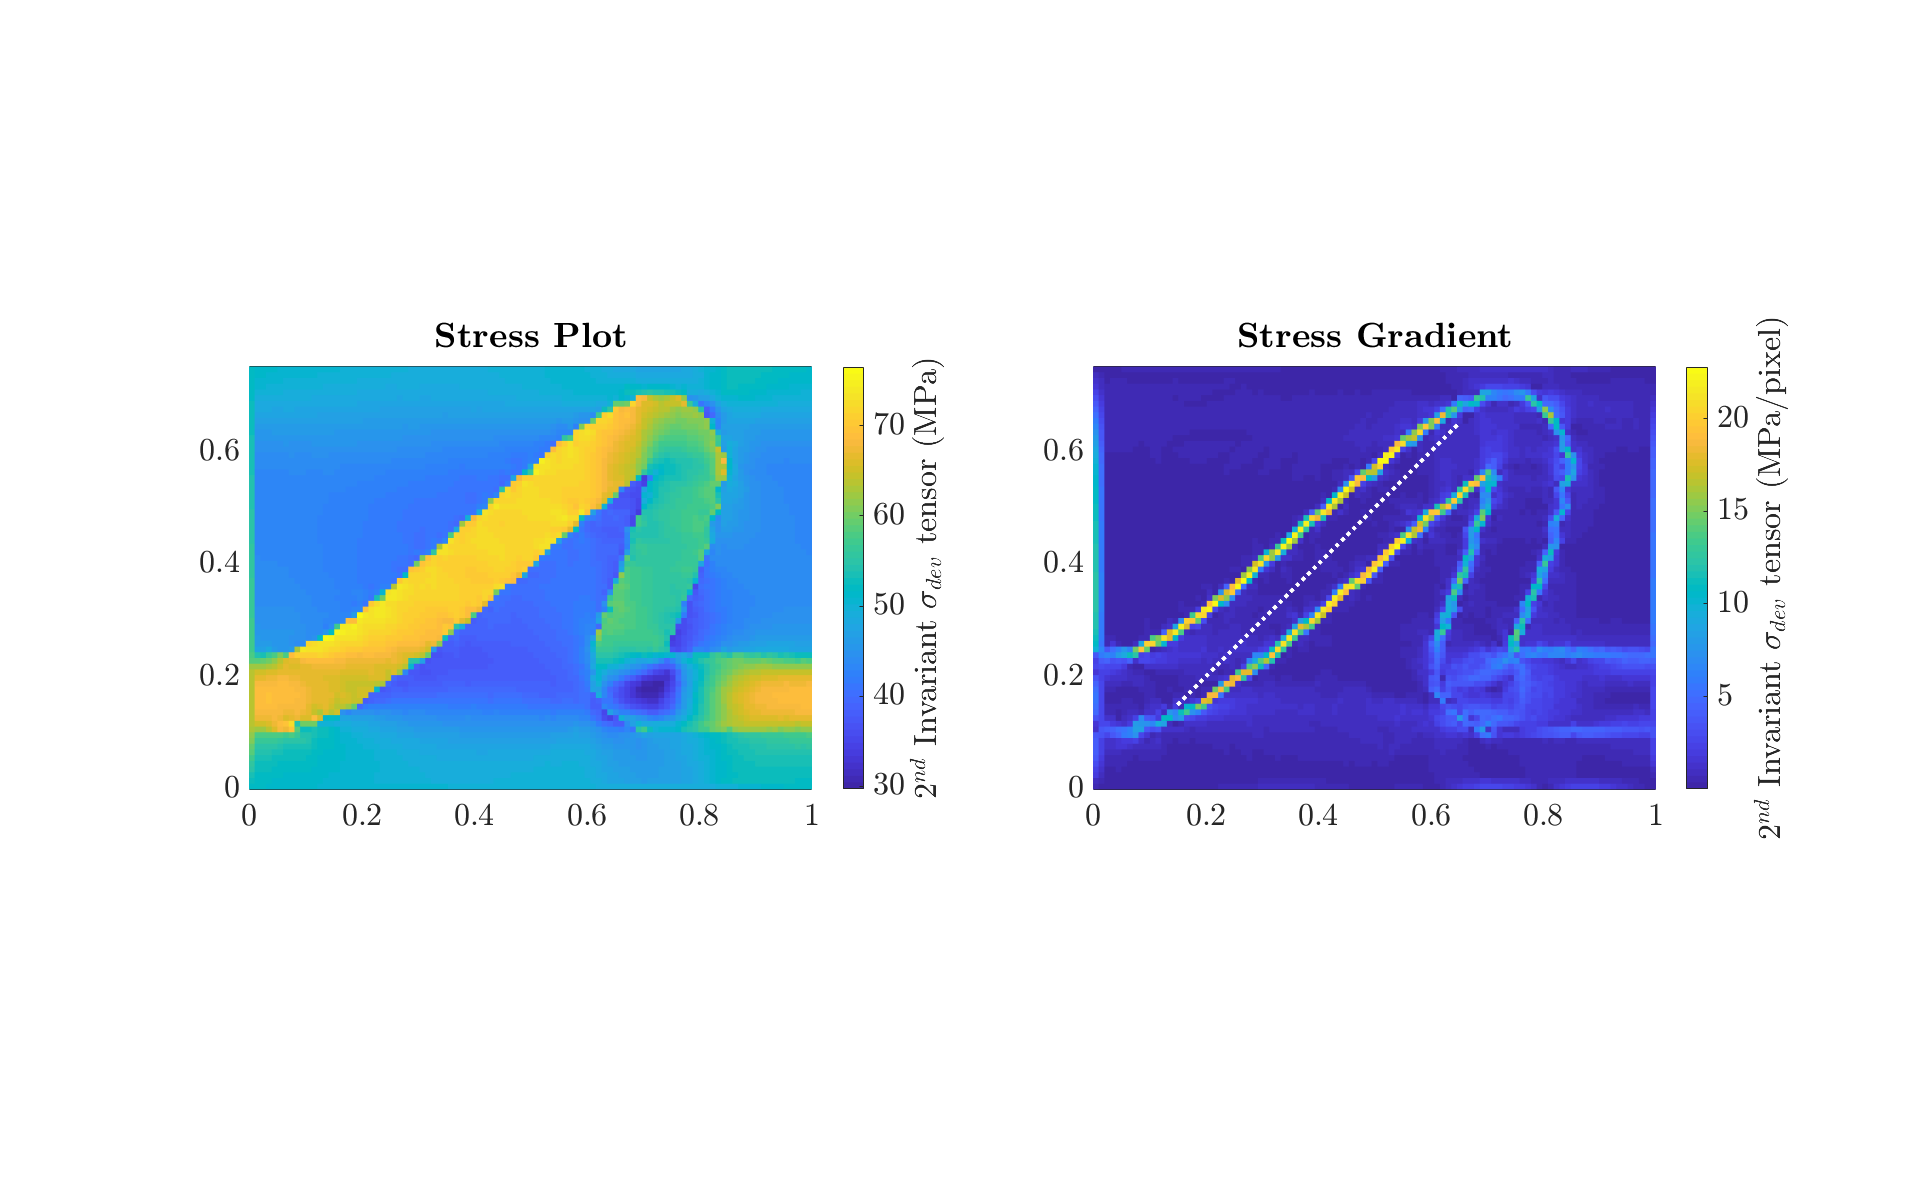



% CREATE A SUBPLOT FIGURE TO COMPARE THE STRESS AND THE STRESS GRADIENT
imageplot = figure('units','normalized','Position',[0 0 1 1]); % initialize plot of the entire domain
set(imageplot,'Renderer','painters','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')

% PLOT STRESS IN THE SUBPLOT
parametersubplot = plc.subplot(imageplot,1,2,1,plc.results);
    title(['\textbf{','Stress Plot','}'],...
        'Interpreter','latex','fontname','Century Schoolbook');
    set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
    c = colorbar;
    c.Label.String = [y_axis_label,' ',y_axis_unit];
    set(c,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)
    set(c.Label,'Interpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)
    caxis auto
    hold on
    % add in the cross section line
    plot([plc.vx1,plc.vx2],[plc.vy1,plc.vy2],'Color','black',...
        'LineStyle',':','LineWidth',3);
    set(gca,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24,...
        'DataAspectRatio',[1 1 1])

% PLOT STRESS GRADIENT IN THE SUBPLOT
gradimagesubplot = plc.subplot(imageplot,1,2,2,plc.results_gradient);
    title(['\textbf{','Stress Gradient','}'],...
        'Interpreter','latex','fontname','Century Schoolbook');
    set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
    c = colorbar;
    c.Label.String = [y_axis_label,' ',y_axis_gradient_unit];
    set(c,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24);
    set(c.Label,'Interpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24);
    caxis auto
    hold on
    % add in the cross section line
    plot(plc.normalize(plc.xc_x),plc.normalize(plc.xc_y), ...
        'Color','white','LineStyle',':','LineWidth',3)
    set(gca,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24,...
        'DataAspectRatio',[1 1 1])

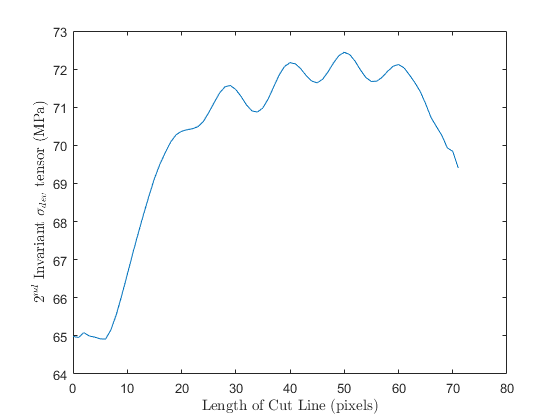


% PLOT THE STRESS ALONG THE LINE OF CROSS SECTION
xcplot = figure; % initialize cut line / cross-section plot
set(xcplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
plot(0:(plc.vertex_distance)/(plc.vertex_distance):...
    ((plc.vertex_distance)),plc.cutline);
    % divide vertex distance by plotlength for normalized x-axis
hold on
xlbl = xlabel([x_axis_label,' ',x_axis_unit]);
ylbl = ylabel([y_axis_label,' ',y_axis_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')

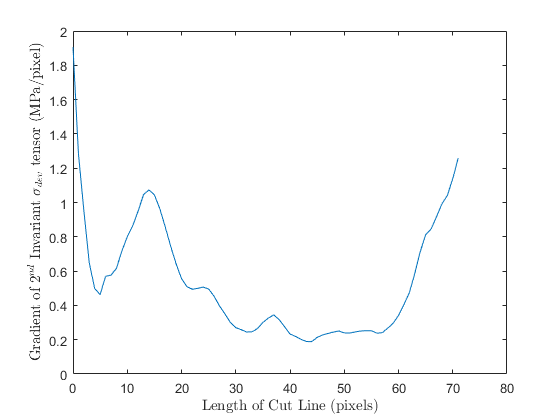


% PLOT THE STRESS GRADIENT ALONG THE LINE OF CROSS SECTION
gradplot = figure; % initialize gradient plot
set(gradplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
plot(0:(plc.grad_vertex_distance)/(plc.grad_vertex_distance)...
    :((plc.grad_vertex_distance)),plc.gradient_cutline);
    % divide vertex distance by plotlength for normalized x-axis
hold on
xlbl = xlabel([x_axis_label,' ',x_axis_unit]);
ylbl = ylabel(['Gradient of ',y_axis_label,' ',y_axis_gradient_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')


% SAVE THE FIGURES TO FILE, IF DESIRED
save_figures = false; % set to true to save the figure outputs
figureList1 = [parameterplot, imageplot, xcplot, gradplot]; % list the figure handles here
h1 = findobj(figureList1, 'flat', 'Type', 'figure');
if (save_figures == true)
    cd(DemoDirectory)
    if (exist(fullfile(pwd, 'Figures'), 'dir') == 0)
        mkdir Figures
    end
    cd('Figures');
    if (exist(fullfile(pwd, project_name), 'dir') == 0)
        mkdir (project_name);
    end
    cd(project_name);
    for i=1:length(h1)      
        saveas(h1(i), [project_name '_Single_Run_Figure_' num2str(h1(i).Number)], 'epsc');
    end
    cd ../../;
end

## (2) Plot multiple PLC runs in which a characteristic (in this case, the frequency of a sawtooth wave) changes from run to run

This second example is a bit more complicated than the first in that it examines the results from multiple PLC runs and masks Phase 2 to exclude it from the calculations.

The "project_name" allows you to define how many PLC analyses to visualize. The more specific the project basename, the more restrictive (fewer PLC runs will be visualized).

Whereas the cross section was explicitly defined by vertices in the previous examples, this example shows how the line of cross section can be automatically generated by detecting the region with the highest gradient of your parameter of interest (in this case, stress).

%%% PERFORM CALCULATIONS AND PLOT RESULTS FOR MULTIPLE RUNS %%%

project_name = 'Sawtooth_frequency'; % root name of the PLC runs of interest
parameter = 'Stress'; % choose between 'Stress' 'Strain' 'Viscosity' or 'PowerDissipationDensity'
temperature_interval = 1; % declare which PLC temperature interval is of interest
stress_strain_interval = 2; % declare which applied macro strain rate or stress 
    % interval is of interest
k_value = 10; % see k-value explainer above
auto_xc_linelength = 0.3; % length of the line of cross section

% PLOTTING PREFERENCES
legend_title = 'Frequency';
legend_loc_xcplot = 'southeast'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
legend_loc_grad_xcplot = 'northeast'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
legend_loc_maxmin = 'northwest'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
run_name_delimiter = '_'; % specify the character separating components of the
    % PLC run name (underscore is recommended)
run_name_legend_component = 3; % specify which component of the PLC run name
    % should be used in the line plot legend
varmag_component = 3; % specify which component of the PLC run name contains the
    % parameter of change
varmag_component_name = 'Frequency'; % specify the name of the parameter of change
x_axis_label = 'Length of Cut Line';
x_axis_unit = '(pixels)';
y_axis_label = '$2^{nd}$ Invariant $\sigma_{dev}$ tensor';
y_axis_unit = '(MPa)';
y_axis_gradient_unit = '(MPa/pixel)';

% CHANGE TO THE DIRECTORY WHERE THE PLC OUTPUT IS STORED
try
    cd(DemoDirectory)
catch
    msg = ['Wrong DemoDirectory supplied. Select the directory ', ...
          'one level above where results (PLC output) are stored.'];
    DemoDirectory = uigetdir(userpath,msg);
    cd(DemoDirectory)
end

list_dir = dir(strcat(project_name,'*'));
legend_items = cell(length(list_dir),1);
plc = PLCobject.empty(length(list_dir),0); % allocate memory for multiple PLC objects

% PERFORM CALCULATIONS ON EACH PROJECT ITEM
for i = 1:length(list_dir)
    cd(list_dir(i).name);
    run = i;
    
    % INITIALIZE THE PLC OBJECT WHILE MASKING PHASE 2
    % AND SPECIFYING A GRID RESOLUTION AND BOUNDARY FITNESS 
    % (default boundary fitness = 0.5, min is 0, max is 1).
    % 
    % NOTE: A higher boundary fitness leads  to a tighter fit 
    % against the grain boundary, which helps when the masked 
    % grain has a complex geometry)
    plc(i) = PLCobject('Stress',temperature_interval,...
        stress_strain_interval,'kValue',k_value, ...
        'nullPhases',2,'boundaryFitness',0.85, ...
        'resolution',200);
    
    % CALCULATE THE STRESS GRADIENT
            plc(i) = plc(i).CalculateGradient;

    % DEFINE A CUT LINE LENGTH AND AUTOMATICALLY FIND
    % THE LINE WHICH CUTS ACROSS THE AREA WITH THE HIGHEST
    % STRESS GRADIENT
    plc(i) = plc(i).SetCutLine(auto_xc_linelength);
    
    legend_items{i} = char(plc(i).fname_components(1,run_name_legend_component));
    legend_items{i} = strrep(legend_items{i}, ',', '.');
    cd ../;
end

imageplot = gobjects(length(list_dir),0);

% CREATE A SUBPLOT FIGURE TO COMPARE THE PARAMETER OF INTEREST AND ITS GRADIENT
for i = 1:length(plc)
    imageplot(i) = figure('units','normalized','Position',[0 0 1 1]); % initialize plot of the entire domain
    set(imageplot(i),'Renderer','painters','GraphicsSmoothing','on');
    set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
    
    % PLOT THE PARAMETER OF INTEREST
    parametersubplot = plc(i).subplot(imageplot(i),1,2,1,plc(i).results);
        title(['\textbf{',strrep(project_name,'_',' '),': ',legend_items{i},'}'],... %'-',char(plc(i).fname_components(run_name_legend_component))],...
            'Interpreter','latex','fontname','Century Schoolbook');
        set(gca, 'visible', 'off') % remove the axes markers
        set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
        c = colorbar;
        c.Label.String = [y_axis_label,' ',y_axis_unit];
        set(c,'TickLabelInterpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24)
        set(c.Label,'Interpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24)
        caxis auto
        hold on
        % add in the cross section line
        plot([plc(i).vx1,plc(i).vx2],[plc(i).vy1,plc(i).vy2],'Color','black',...
            'LineStyle',':','LineWidth',3);
        set(gca,'TickLabelInterpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24)
    
    % PLOT THE GRADIENT OF THE PARAMETER OF INTEREST
    gradimagesubplot = plc(i).subplot(imageplot(i),1,2,2,plc(i).results_gradient);
        title(['\textbf{','Gradient of ',strrep(project_name,'_',' '),': ',legend_items{i},'}'],...%'-',char(plc(i).fname_components(run_name_legend_component)),],...
            'Interpreter','latex','fontname','Century Schoolbook');
        set(gca, 'visible', 'off') % remove the axes markers
        set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
        c = colorbar;
        c.Label.String = [y_axis_label,' ',y_axis_gradient_unit];
        set(c,'TickLabelInterpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24);
        set(c.Label,'Interpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24);
        caxis auto
        hold on
        % add in the cross section line
        plot(plc(i).normalize(plc(i).xc_x),plc(i).normalize(plc(i).xc_y), ...
            'Color','white','LineStyle',':','LineWidth',3)
        % add in a circle to highlight the area of maximum gradient
        maxcircle = plot(plc(i).normalize(plc(i).max_gradient_col), ...
            plc(i).normalize(plc(i).max_gradient_row),'o', ...
            'MarkerSize',10,'LineWidth',2,'Color','red');
        Lgrad = legend(maxcircle,'Maximum Gradient','Location','northeast');
        set(Lgrad,'Interpreter','latex',...
            'fontname','Century Schoolbook','fontsize',18);
        set(gca,'TickLabelInterpreter','latex',...
            'fontname','Century Schoolbook','fontsize',24)
end

% PLOT THE MAX-MIN OF THE PARAMETER OF INTEREST
minmaxplot = figure; % initialize plot of maximum-minimum value
set(minmaxplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
max_less_min = zeros(length(plc),2);
c = linspace(1,10,length(max_less_min));
marker_size = 50;
for i = 1:length(plc)
    max_less_min(i,:) = plc(i).MaxLessMin(varmag_component);
    scatter(max_less_min(i,1),max_less_min(i,2),marker_size,c(i),...
        'filled','MarkerEdgeColor','black')
    hold on
end
colormap(jet)
L3 = legend(legend_items,'Location',legend_loc_maxmin);
L3_title = get(L3,'title');
set(L3,'Interpreter','latex',...
    'fontname','Century Schoolbook');
set(L3_title,'string',legend_title,'Interpreter','latex',...
    'fontname','Century Schoolbook');
title(['\textbf{','Maximum - Minimum Stress Along Line of Cross Section','}'],...
        'Interpreter','latex','fontname','Century Schoolbook');
xlbl = xlabel(varmag_component_name);
ylbl = ylabel([y_axis_label,' ',y_axis_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')

% DISPLAY THE MAXIMUM STRESS VALUE FOR ALL FREQUENCIES
maxmlm = zeros(1,length(plc));
for i = 1:length(plc)
maxmlm(i) = max(max_less_min(i,2));
end
maxmaxmlm = max(maxmlm);
[~,maxparam_plcnum] = find(maxmlm==maxmaxmlm);
fprintf('%s','MAXLESSMIN: The maximum ',parameter,' along the XC line is: ',...
    maxmaxmlm*(1e-9),' GPa when ',varmag_component_name,...
    ' equals ',legend_items{maxparam_plcnum});

MAXLESSMIN: The maximum Stress along the XC line is: 9.690819e+00 GPa when Frequency equals 1.00

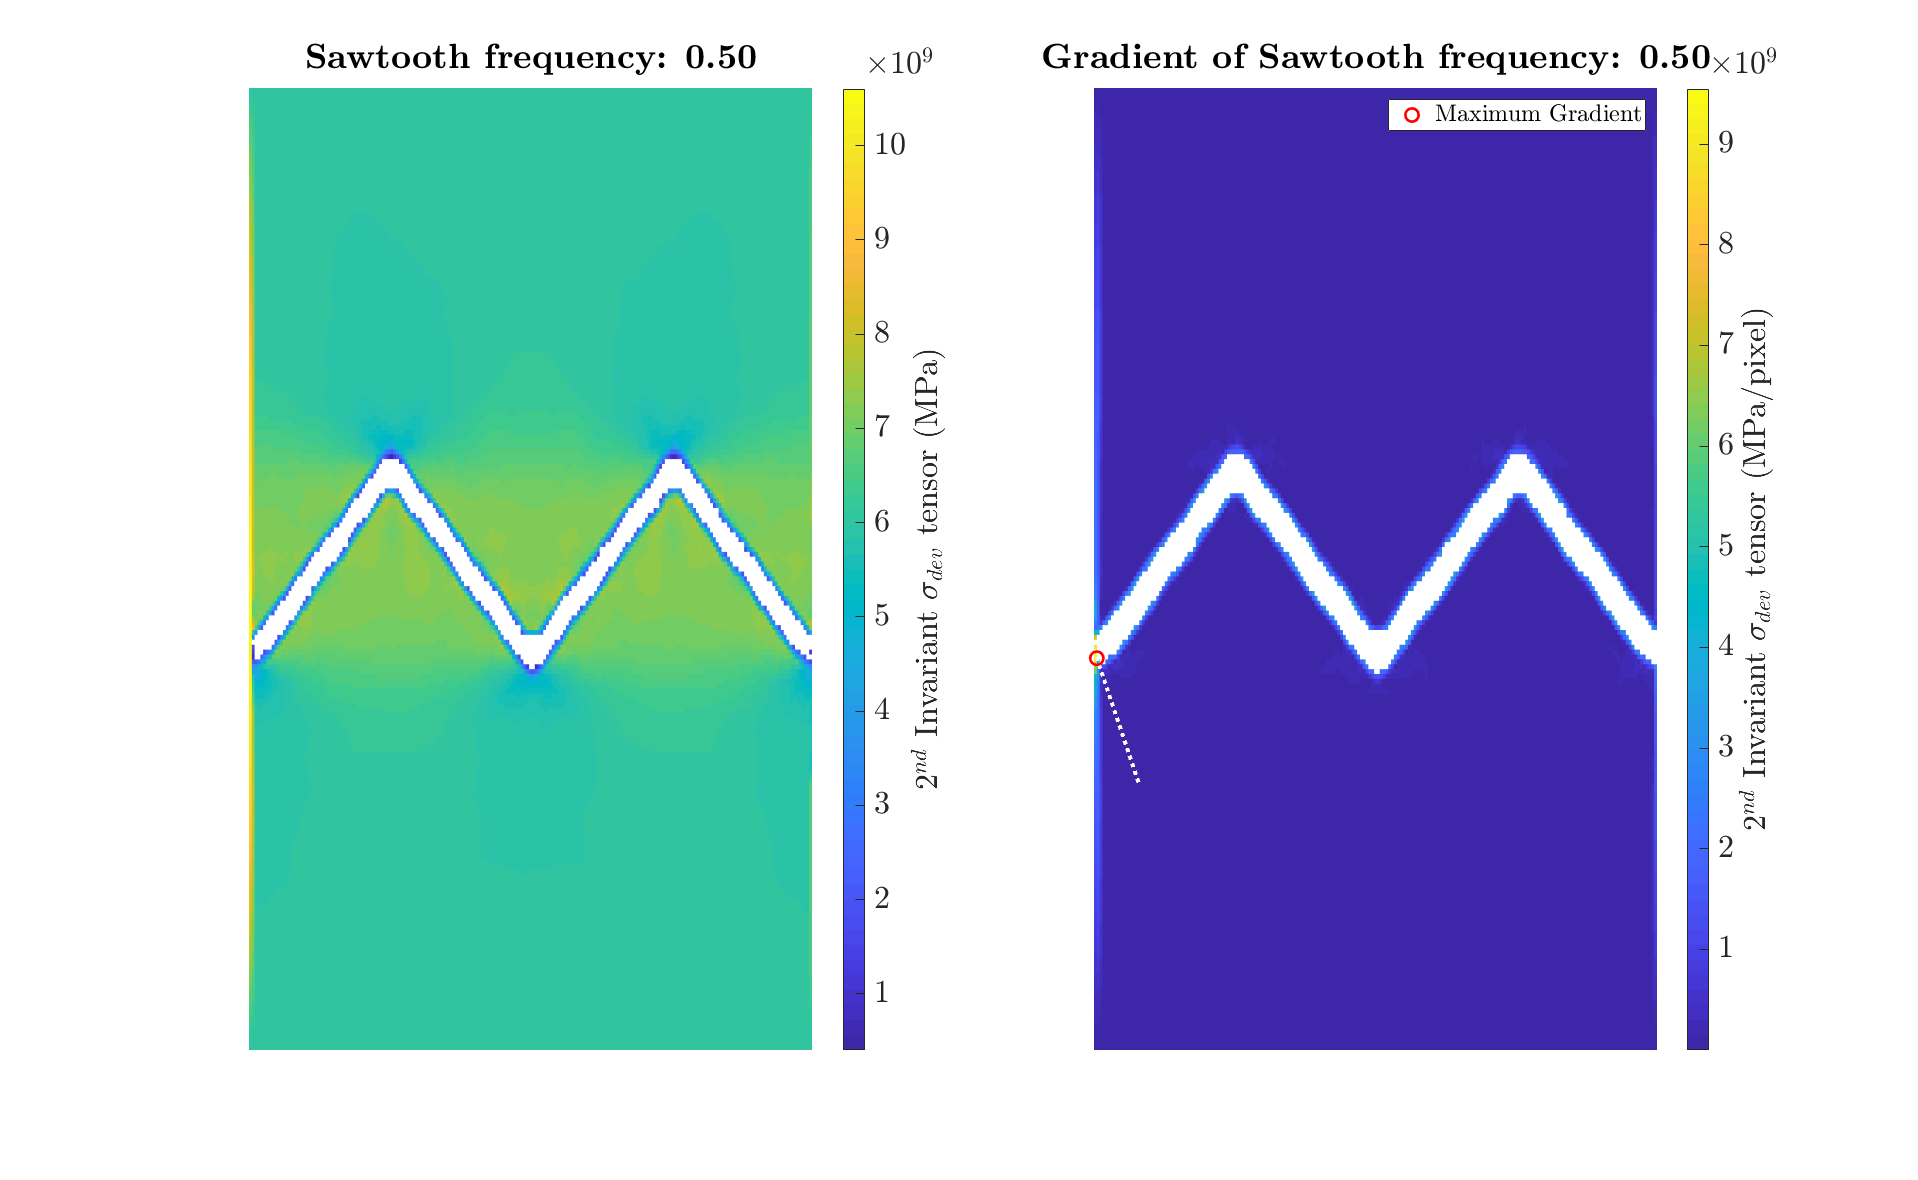

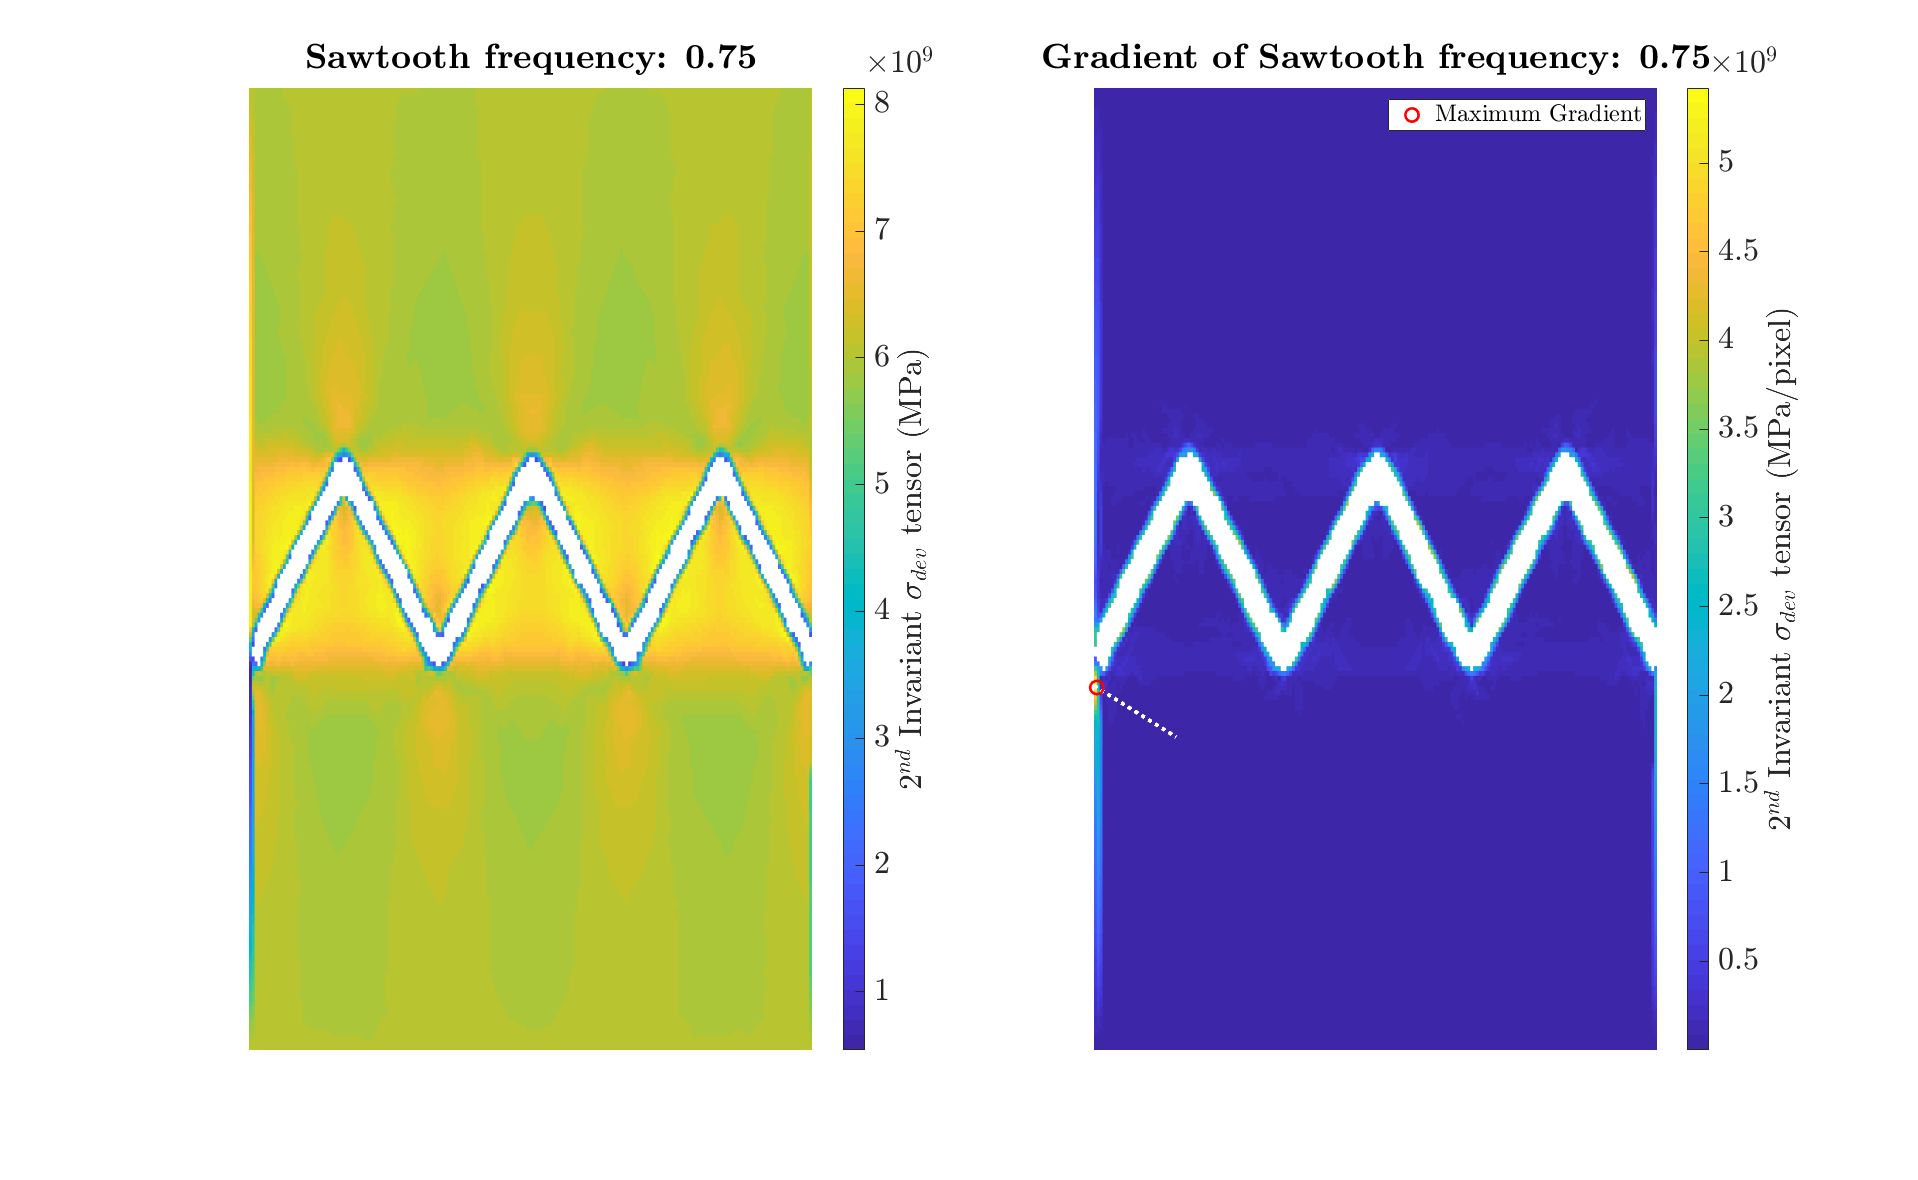

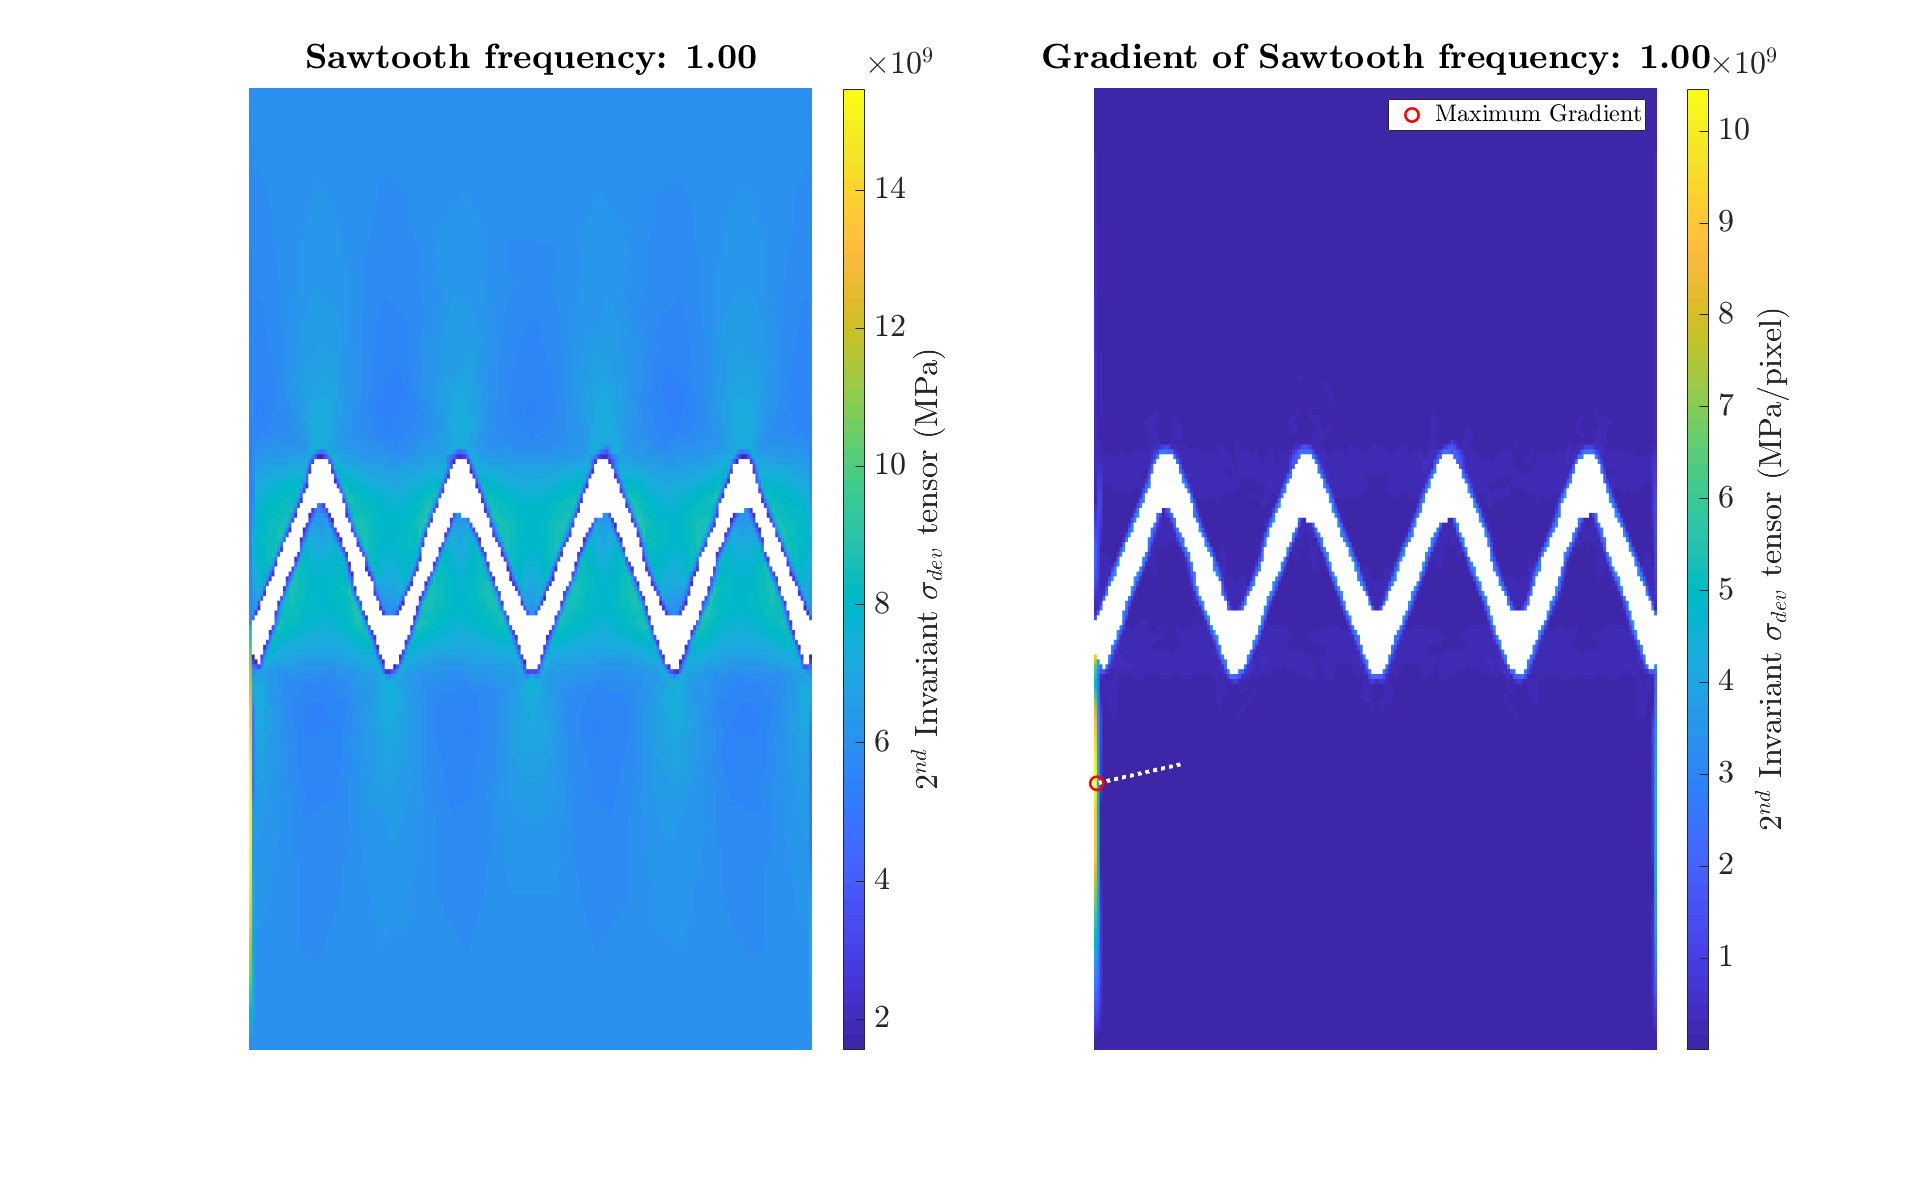

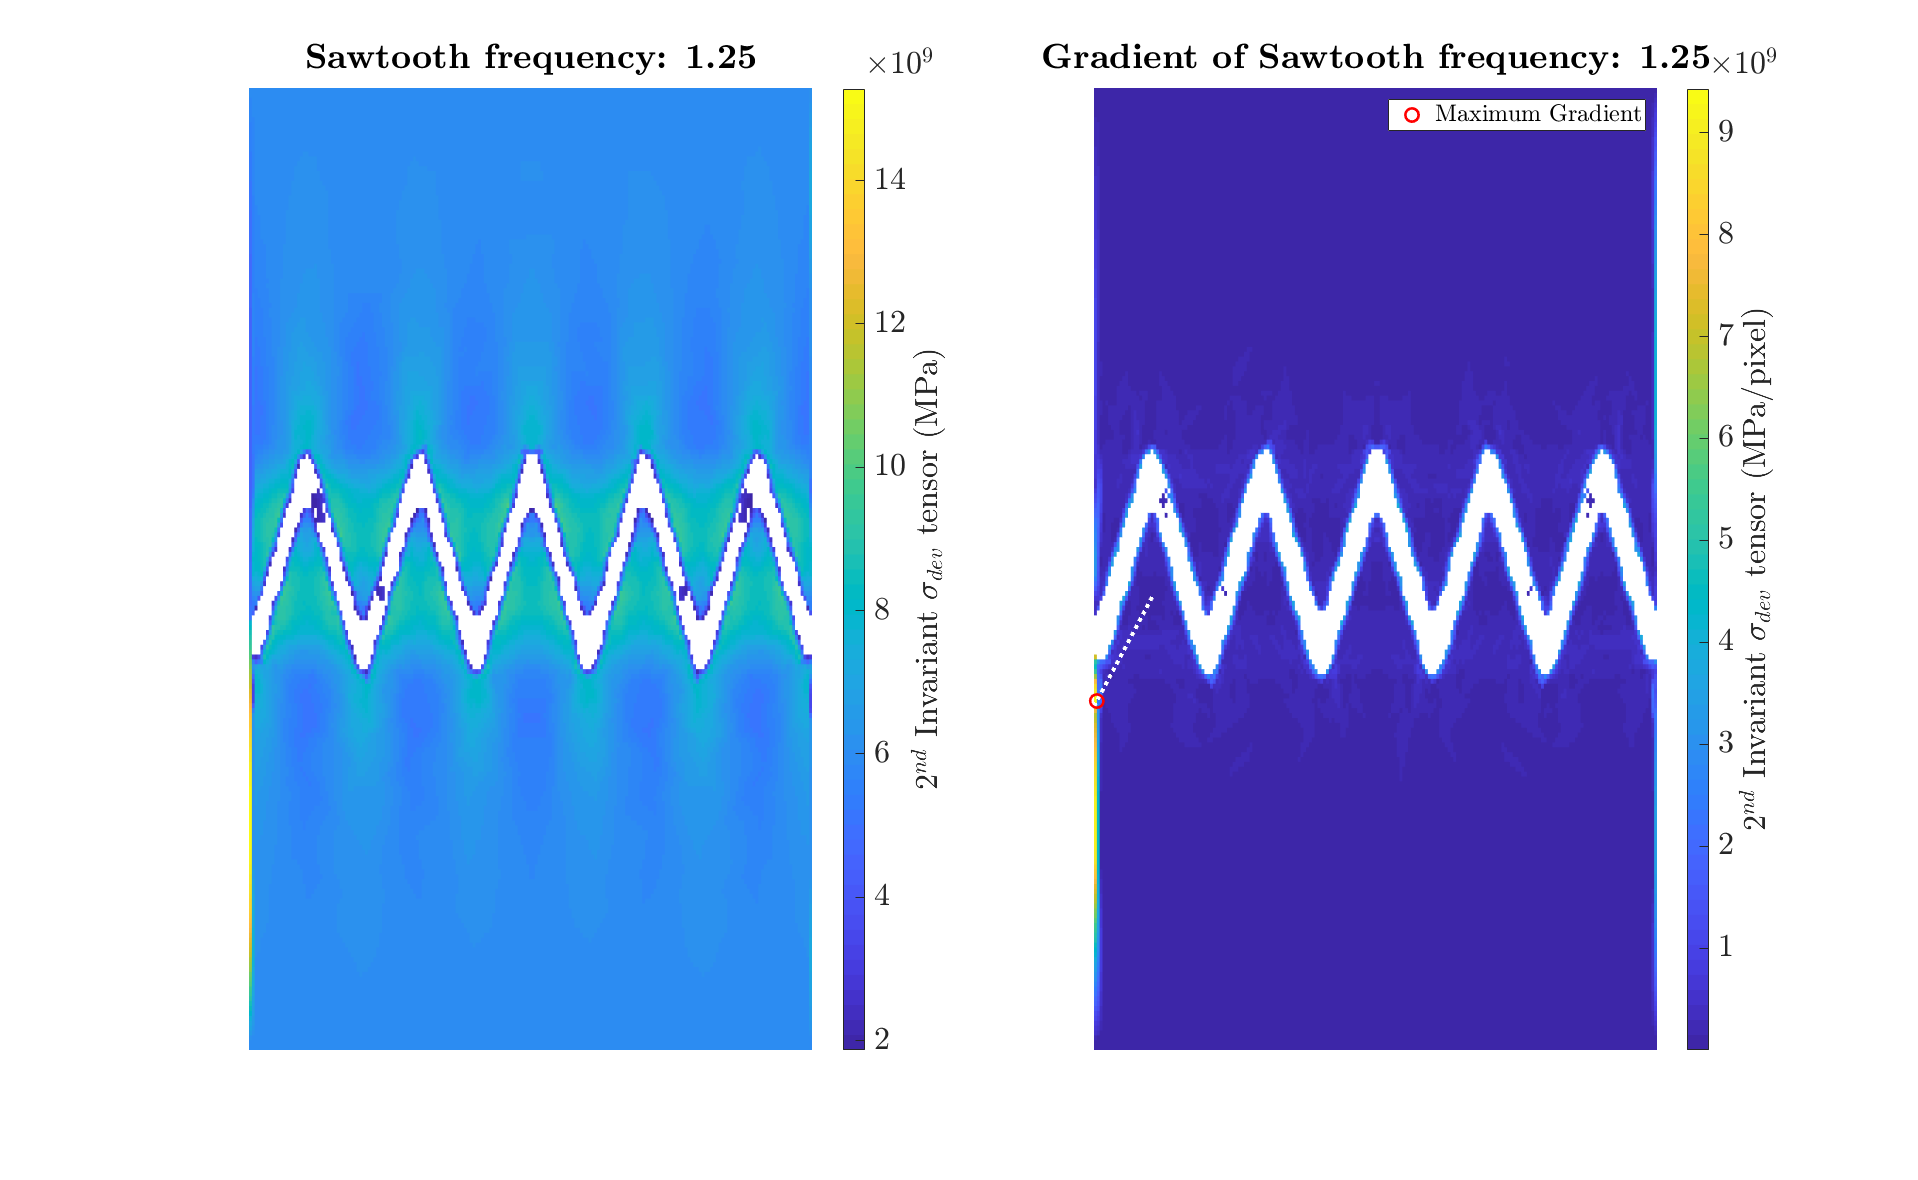

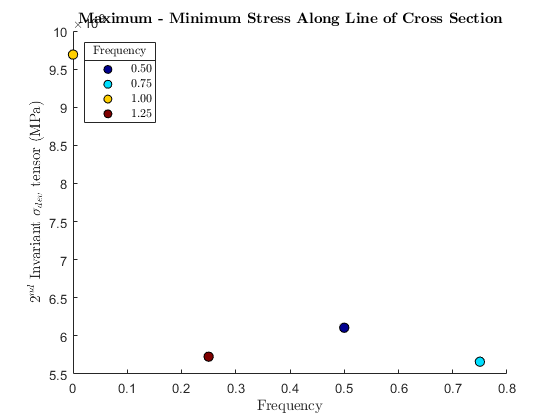


% SAVE THE FIGURES TO FILE, IF DESIRED
save_figures = true; % set to true to save the figure outputs
figureList2 = [imageplot, minmaxplot]; % list the figure handles here
h2 = findobj(figureList2, 'flat', 'Type', 'figure');
if save_figures == true
    cd(DemoDirectory)
    if (exist(fullfile(pwd, 'Figures'), 'dir') == 0)
        mkdir Figures
    end
    cd('Figures');
    if (exist(fullfile(pwd, project_name), 'dir') == 0)
        mkdir (project_name);
    end
    cd(project_name);
    for i=1:length(h2)      
        saveas(h2(i), [project_name '_Multiple_Run_Figure_' num2str(h2(i).Number)], 'epsc');
    end
    cd ../../;
end